% Ex:3 Illustarting rSVD in image processing
clc;
clear all; 
close all; 
A=imread('lena512color.tiff');
size(A)

ans =    512   512     3


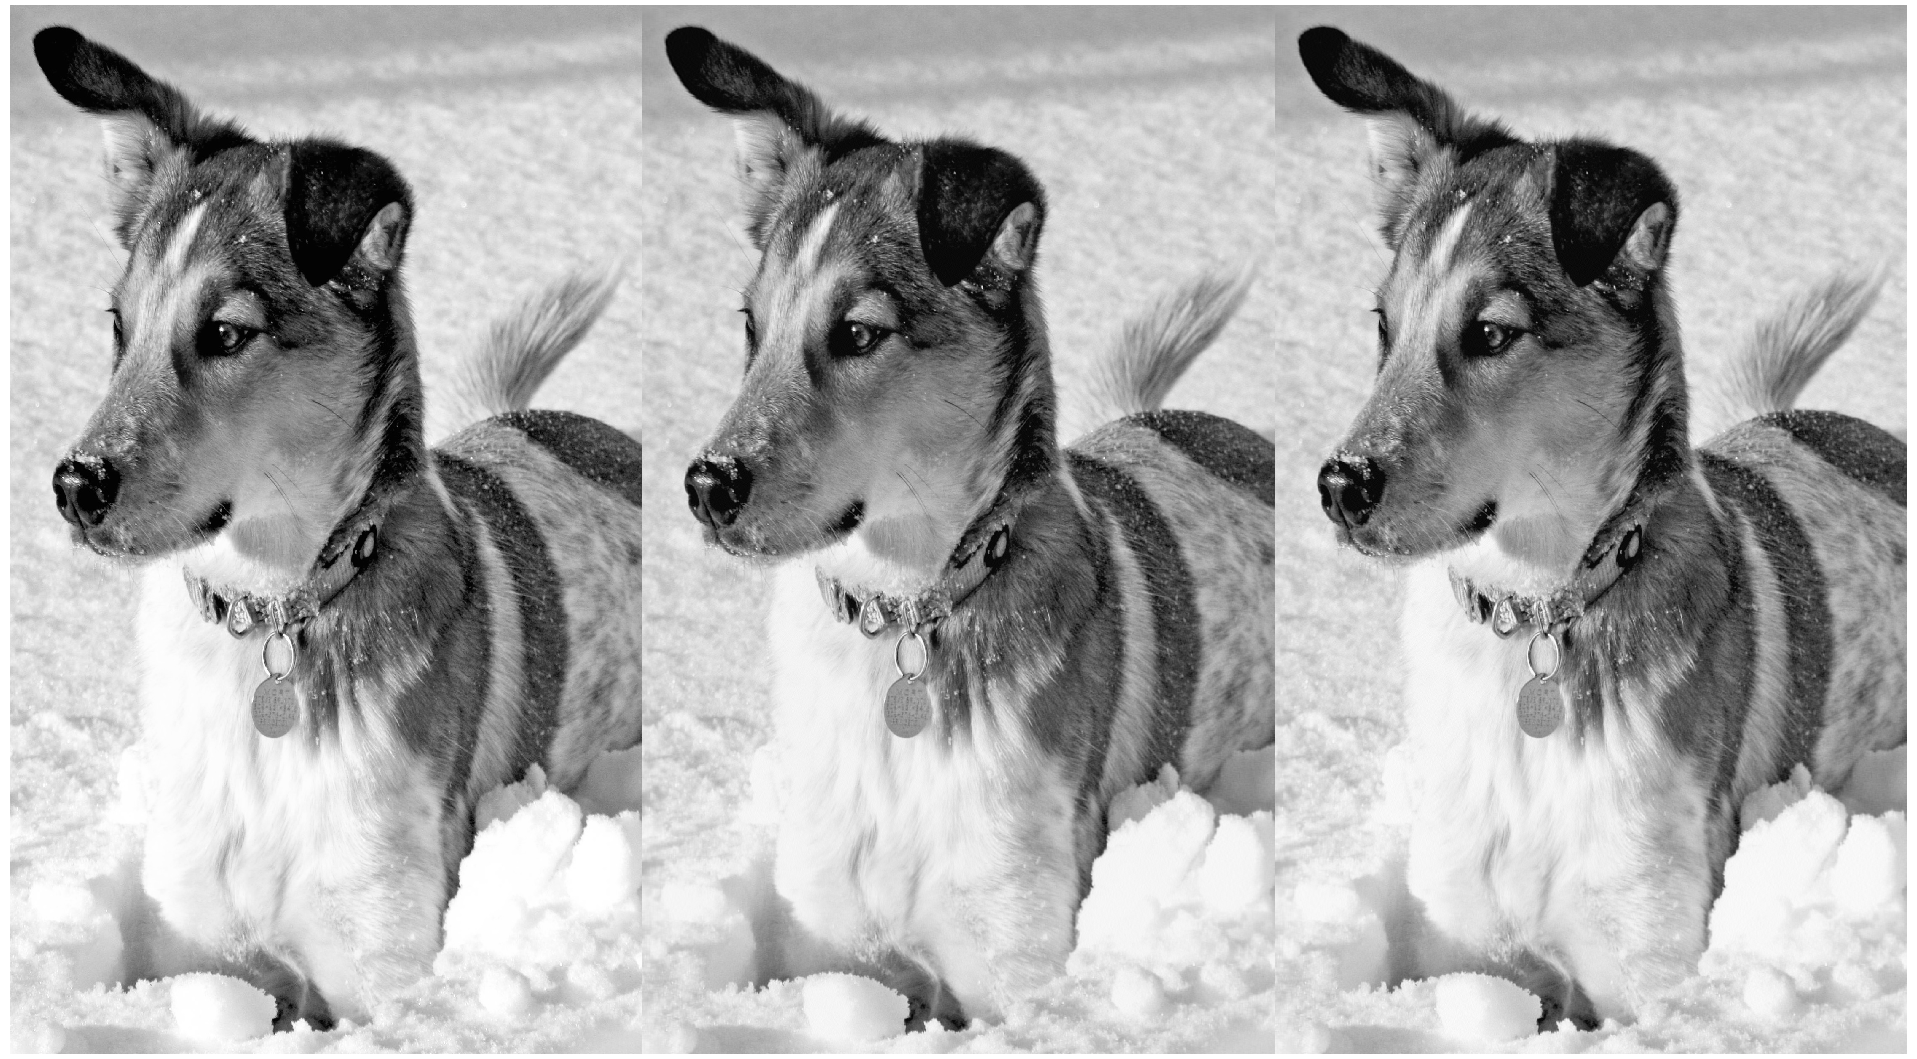

X=double(rgb2gray(A));

% Deterministic SVD
[U,S,V] = svd(X,'econ');    

r = 400; % Target rank
q = 1;   % Denotes no of Power iterations
p = 5;   % Oversampling parameter
[rU,rS,rV] = rsvd(X,r,q,p); % Randomized SVD

%% Reconstruction
XSVD = U(:,1:r)*S(1:r,1:r)*V(:,1:r)';     % SVD approx.
errSVD = norm(X-XSVD,2)/norm(X,2);
XrSVD = rU(:,1:r)*rS(1:r,1:r)*rV(:,1:r)'; % rSVD approx.
errrSVD = norm(X-XrSVD,2)/norm(X,2);

%% Plot
ax1 = axes('Position',[.005 .005 .33 .99]);
imagesc(X), axis off, colormap gray

ax2 = axes('Position',[.335 .005 .33 .99]);
imagesc(XSVD), axis off

ax3 = axes('Position',[.665 .005 .33 .99]);
imagesc(XrSVD), axis off

set(gcf,'Position',[100 100 2114 1000])
set(gcf,'PaperPositionMode','auto')
print('-depsc2', '-loose' , 'rSVD.eps');

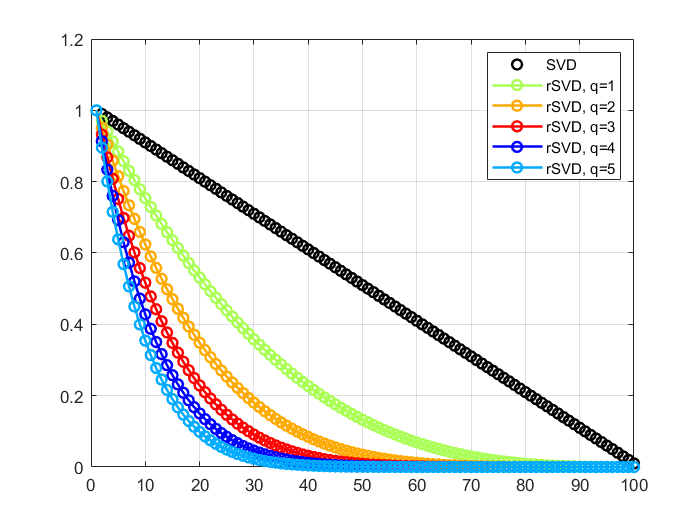

% Power iterations
clc;
clear all;
close all;


X = randn(1000,100);
[U,S,V] = svd(X,'econ');
S = diag(1:-.01:.01);
X = U*S*V';

plot(diag(S),'ko','LineWidth',1.5)
hold on
CC = jet(11); % Matrix contains jet colormap
Y = X;
for q=1:5 
    Y = X'*Y;
    Y = X*Y;
    [Uq,Sq,Vq] = svd(Y,'econ');
    plot(diag(Sq),'-o','Color',CC(mod(2*q+4,11)+1,:),'LineWidth',1.5);
end
grid on;
legend('SVD','rSVD, q=1','rSVD, q=2','rSVD, q=3','rSVD, q=4','rSVD, q=5');